# Analiza częstotliwościowa

generowanie probek:

N = 100;
fs1kHz = 1000;
x = 50*sin(2*pi*50*[0:1/fs1kHz:N*1/fs1kHz-1/fs1kHz]) + ...
    100*sin(2*pi*100*[0:1/fs1kHz:N*1/fs1kHz-1/fs1kHz]) + ...
    150*sin(2*pi*150*[0:1/fs1kHz:N*1/fs1kHz-1/fs1kHz]);

% begin exc01
wk = @(k,n) sk(k,N)*cos(pi*(k/N)*(n+0.5));

% generate matrix A
A = zeros(N,N);
for k=0:N-1
    for n=0:N-1
        A(k+1,n+1) = wk(k,n);
    end
end
% end exc01

% begin exc02
S = A.';
% end exc02

prezentacja danych:

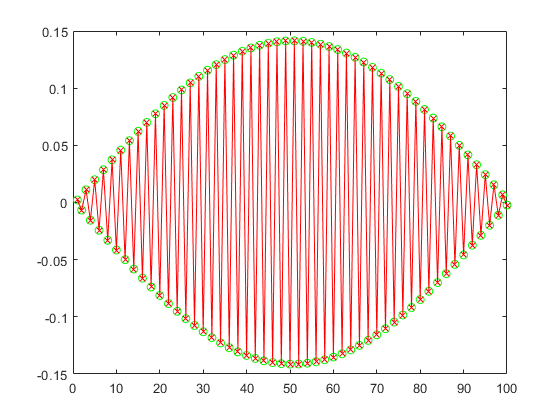

clf
figure
for i=1:N
    clf
    %disp("A: " + A(N,:))
    %disp("S: " + S(:,N)')
    %plot(1:N,A(N,:))
    %plot(1:N,S(:,N)')
    plot(A(i,:),'g-o');
    hold on;
    plot(S(:,i),'r-x');
    pause(0.1)
end

Analiza **y=Ax**

y=A*x';

disp(y');

  Columns 1 through 12

   -0.0000  130.4045   -0.0000  135.5931    0.0000  148.6294    0.0000  180.8181   -0.0000  334.2055  -55.3079 -101.5562

  Columns 13 through 24

    0.0000   61.5363    0.0000  118.2364    0.0000  192.3193   -0.0000  491.5409 -218.5080 -349.5589    0.0000  -43.2782

  Columns 25 through 36

   -0.0000   49.2466    0.0000  154.5654   -0.0000  569.6156 -481.5296 -624.8293    0.0000 -217.6785   -0.0000 -133.0798

  Columns 37 through 48

    0.0000  -95.4081    0.0000  -73.7597    0.0000  -59.5857    0.0000  -49.5400    0.0000  -42.0307    0.0000  -36.1980

  Columns 49 through 60

   -0.0000  -31.5342   -0.0000  -27.7191   -0.0000  -24.5399    0.0000  -21.8495   -0.0000  -19.5426   -0.0000  -17.5420

  Columns 61 through 72

    0.0000  -15.7893    0.0000  -14.2399   -0.0000  -12.8589   -0.0000  -11.6185   -0.0000  -10.4965    0.0000   -9.4747

  Columns 73 through 84

    0.0000   -8.5381    0.0000   -7.6743    0.0000   -6.8728   -0.0000   -6.1245    0.0000   -

function s = sk(k,N)
    if k==0
        s = sqrt(1/N);
        return
    end
    s = sqrt(2/N);
end